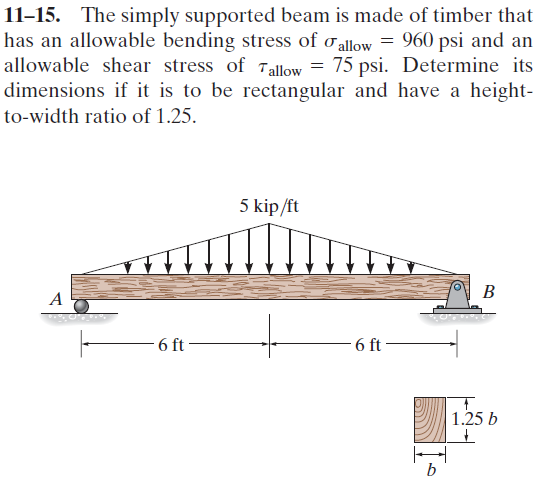

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-15P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-15P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
w1 = findpoly(1, 'thru', [0 0], 'thru', [6*u.ft -5*u.kip/u.ft]);
w2 = findpoly(1, 'thru', [6*u.ft -5*u.kip/u.ft], 'thru', [12*u.ft 0]);
B_min = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 12*u.ft);
b = b.add('distributed', 'force', w1, [0 6]*u.ft);
b = b.add('distributed', 'force', w2, [6 12]*u.ft, [false true]);
b.L = 12*u.ft;

# section properties

B = sym('B', 'positive');
H(B) = 1.25*B;
b.I = B*H^3/12;
A = B*H;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{16\,x\,{\left(180\,{\mathrm{ft}}^{2}-x^{2}\right)}^{2}}{375\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{16\,\left(x-12\,\mathrm{ft}\right)\,{\left(-x^{2}+24\,x\,\mathrm{ft}+36\,{\mathrm{ft}}^{2}\right)}^{2}}{375\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{16\,\left(x-6\,\mathrm{ft}\right)\,\left(x+6\,\mathrm{ft}\right)\,\left(180\,{\mathrm{ft}}^{2}-x^{2}\right)}{75\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{16\,\left(x-6\,\mathrm{ft}\right)\,\left(x-18\,\mathrm{ft}\right)\,\left(-x^{2}+24\,x\,\mathrm{ft}+36\,{\mathrm{ft}}^{2}\right)}{75\,B^{4}\,\text{E}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{5\,x\,\left(108\,{\mathrm{ft}}^{2}-x^{2}\right)}{36}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{5\,\left(x-12\,\mathrm{ft}\right)\,\left(x^{2}-24\,x\,\mathrm{ft}+36\,{\mathrm{ft}}^{2}\right)}{36}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{5\,\left(x-6\,\mathrm{ft}\right)\,\left(x+6\,\mathrm{ft}\right)}{12}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{5\,\left(x-6\,\mathrm{ft}\right)\,\left(x-18\,\mathrm{ft}\right)}{12}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{5\,x}{6}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ \frac{5\,\left(x-12\,\mathrm{ft}\right)}{6}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & 15\,\mathrm{kip}\\ \mathrm{Rb} & 15\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

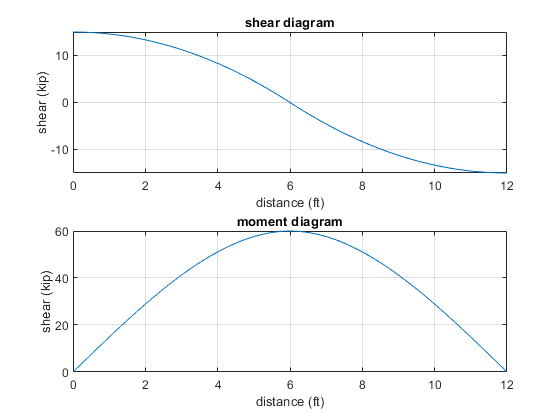

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum loads

assume(0 < x & x < b.L);
xmax = solve(v == 0);
M_max = m(xmax)

$$M\_max = 60\,\mathrm{ft}\,\mathrm{kip}$$

V_max = v(b.L)

$$V\_max = -15\,\mathrm{kip}$$

# maximum stresss

C = H/2;
sigma_max = rewrite(M_max, [u.psi u.in])*C/b.I

$$sigma\_max(B) = \frac{2764800}{B^{3}}\,{\mathrm{in}}^{3}\,\mathrm{psi}$$

tau_max = 3*abs(rewrite(V_max, [u.psi u.in]))/(2*A)

$$tau\_max(B) = \frac{18000}{B^{2}}\,{\mathrm{in}}^{2}\,\mathrm{psi}$$

# minimum beam dimension

sigma_allow = 960*u.psi;
B_min.bending = solve(sigma_max == sigma_allow);
B_min.bending = simplify(B_min.bending);
B_min_bending = vpa(B_min.bending, 4) %#ok<NASGU> 

$$B\_min\_bending = 14.23\,\mathrm{in}$$

tau_allow = 75*u.psi;
B_min.shear = solve(tau_max == tau_allow);
B_min.shear = simplify(B_min.shear);
B_min_shear = vpa(B_min.shear, 4) %#ok<NASGU> 

$$B\_min\_shear = 15.49\,\mathrm{in}$$

B_min_vals = [B_min.bending B_min.shear];
loc = (sigma_max(B_min_vals) <= sigma_allow) & ...
      (tau_max(B_min_vals) <= tau_allow);
B_min.limit = B_min_vals(isAlways(loc));
B_min_limit = vpa(B_min.limit, 4) %#ok<NASGU> 

$$B\_min\_limit = 15.49\,\mathrm{in}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear B_min_bending;
clear B_min_shear;
clear B_min_vals loc B_min_limit;